# **Exercício 3 - cap 7**

**Discente: **Raphael Ramos da Silva

Utilizando os laboratórios disponibilizados no [**l ink**](http://utam.gg.utah.edu/Classes/ML/LAB1/Chapter.Book.SVM/lab.html):

- Compare a filtragem de ruídos de migração usando FCNN e SVM com Kernel RBF.

- Envie os resultados com devidas análises em um notebook (Python ou Matlab).

**Try to train the model with an unbalanced training set. For examples, we have 50 artifacts points and 3 reflector points in the training set.**

Ao invés de manualmente escolher os pontos a cada execução do script `comapre_main.m`, este foi modificado para ler os pontos do arquivo `xzpicks.mat`, no qual há essa desbalanceamento de rótulos.

Alterando as variáveis n_refl e n_arti no compapre_main.m para

n_refl=3;n_arti=50;

Temos os seguintes resultados de classificação dos pontos

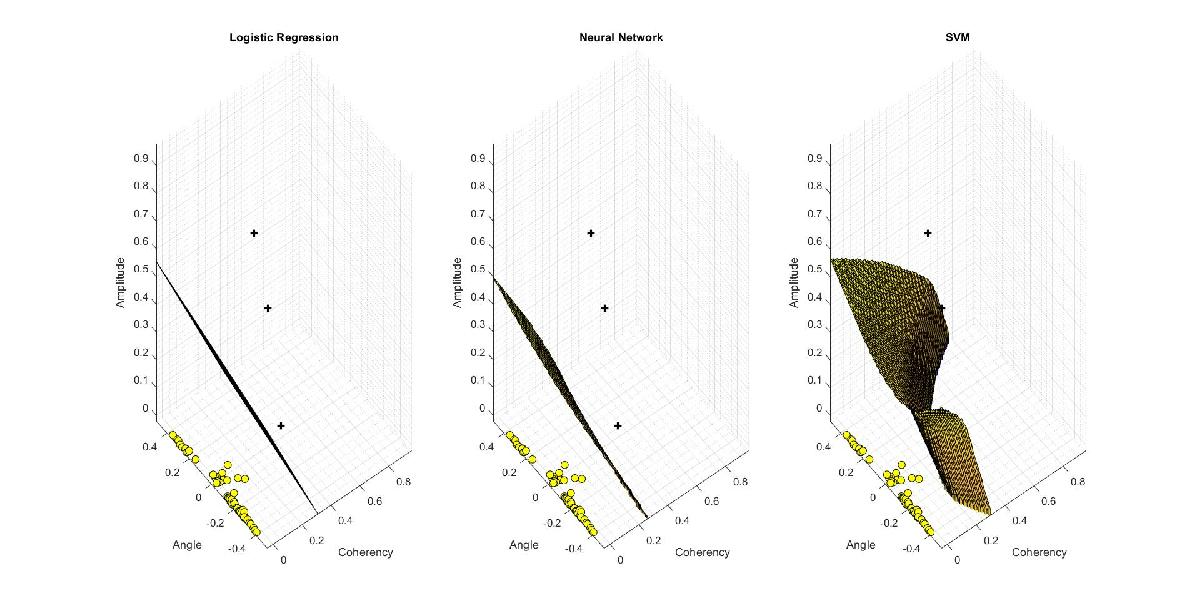

E os resultados das migrações filtradas para cada um dos métodos utilizados

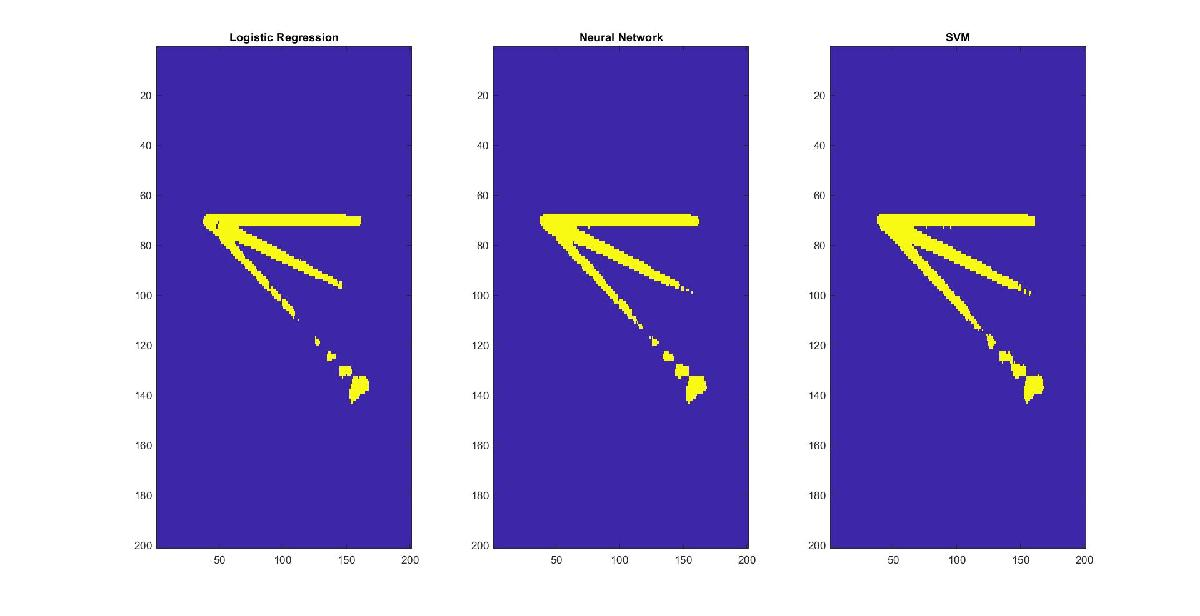

No resultado da migração dos três métodos, a máscara amarela manteve a geometria linear dos três refletores. Além disso, os arcos de difração foram removidos com sucesso. Mas, um aspecto que deixou a desejar nos três métodos foi a permanência do *aliasing* no terceiro evento.

**Modify the program as follows: (1) For each image point in the migration image, open a local window with size of winx by winz around this image point. (2) Unroll this local image to the size of 1 by winx*winz and saved as one example in the training set. so in this case, the dimension of input features are winx by winz).**

O script `comapre_main.m` calcula 3 atributos por ponto (cohe, angl, engy) e cada exemplo de treinamento vira algo como [cohe, angl, engy].

Agora, pelo o que é solicitado no enunciado, para cada ponto da imagem de migração, deve-se:

 1. Pegar uma janela local centrada nesse ponto, com tamanho winx × winz;

 2. “Desenrolar” essa janela em um vetor de tamanho 1 × (winx*winz);

 3. Usar esse vetor como um exemplo do treinamento. Este deve ser rotulado como 1 (refletor) ou 0 (artefato)

O script `comapre_janela_main.m` implementa as transformações, treinamento e inferência comentados nos paragrafos seguintes. Esse *script* carrega as estruturas de dados do arquivo `xzpicks_50artif_50ref.mat`, no qual possui um conjunto de pontos balanceados anotados com 50 refletores e 50 artefatos.

Cada amostra deixa de ser 3 números e passa a ser a assinatura completa da vizinhança ao redor do ponto. Assim, a matriz X tera winx*winz colunas, e não 3.

Montar essa matriz X eh possivel graças a função `montar_janela.m`, que extrai uma janela de um ponto qualquer da imagem migrada, escolhido pelo usuario e, apos achata-la (*flatenning*), insere-a em uma linha de X. Quando a janela está próxima da borda, `montar_janela.m` desloca a janela para mantê-la completamente dentro da imagem.

A matriz de treinamento é normalizada por coluna: calculamos a média dos pixels entre as coordenadas de cada janela (${\overline{X} }_{1\times 25}$), a janela com os maiores pixels (${\mathrm{max}\left(X\right)}_{1\times 25}$) e menores (${\textrm{m}\mathrm{in}\left(X\right)}_{1\times 25}$). Assim, o *dataset* normalizado é obtido subtraindo de cada janela (coluna) a média e dividindo pela diferença entre o mínimo e máximo.

A seguir considerações sobre os três métodos de classificação que precisaram ser adaptados:

A *Regressão Logística* continua usando uma coluna de intercepto, mas agora recebe 25 entradas normalizadas em vez de três. Durante a classificação da imagem, uma janela é extraída para cada posição, normalizada com `X_mean` e `X_scale` calculados no treinamento e então passada ao modelo. Dessa forma, a mesma transformação usada no treinamento é aplicada na inferência.

A *Rede Neural* recebia os três atributos (ângulo, coerência e amplitude) e criava termos quadráticos e produtos cruzados, totalizando dez entradas incluindo o intercepto. Na versão por janelas, essa expansão manual foi eliminada. Assim, as winx × winz posições da janela são utilizadas diretamente como entradas da rede. Na inferência, cada janela é extraída e normalizada antes de passar pelas seguintes camadas: camada oculta (aplicação da matriz de pesos `Theta1)` e saída (aplicação da matriz de pesos `Theta2`).` A` saída é convertida para uma classe binária (0 ou 1) usando o limiar `0.5`

A *SVM *continua sendo treinada com kernel gaussiano, usando os mesmos valores principais `C` (penalização) e `sigma `(largura do kernel Gaussiano). Entretanto, `X` agora contém os vetores de 25 posições das janelas. Na classificação, cada janela é extraída, normalizada com as estatísticas do treinamento e enviada para `svmPredict2`. O resultado é armazenado em `mig_result3`.

**Train the model and compare the predicted classes to the actual classes.**

Após executar `comapre_janela_main.m` com um *dataset* balanceado de 50 refletores e 50 artefatos, 

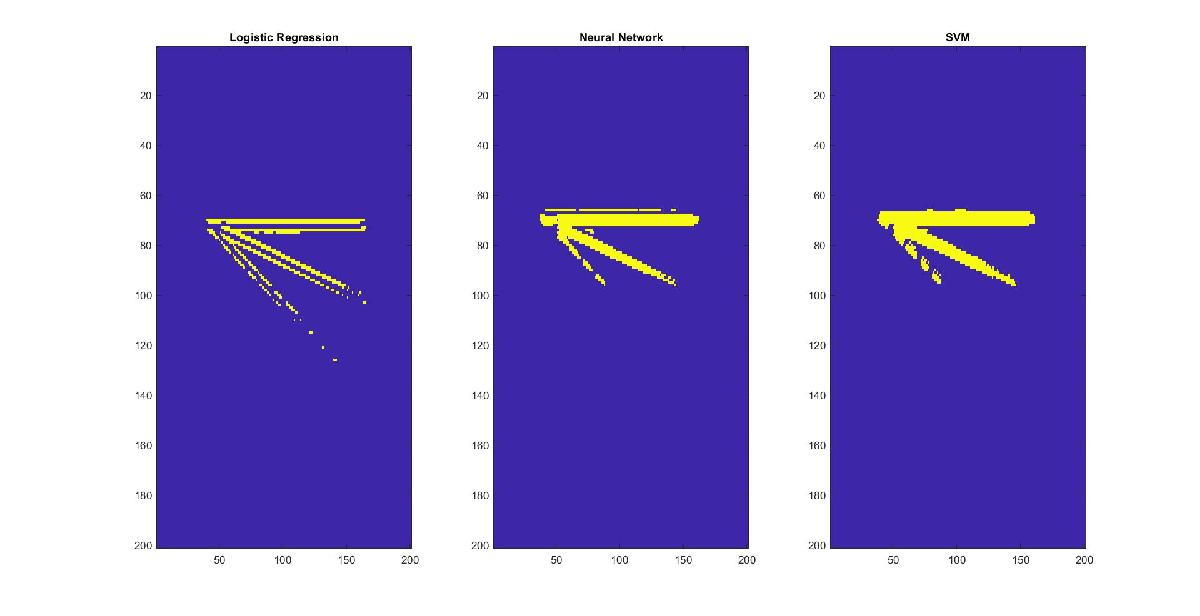

Pelos resultados obtidos, a Regressão Logística deixa rastros visíveis de ruído pontilhado ao longo das diagonais da imagem. A Rede Neural e o SVM, por outro lado, mostram um desempenho superior na supressão desses artefatos de migração, entregando uma imagem final mais limpa e destacando melhor as estruturas refletoras reais. Entre, os três metodos, o SVM demonstrou maior precisão na limpeza de artefatos de migração espalhados (como os pontos dispersos na parte inferior da primeira imagem e o ruído pontilhado nas diagonais da segunda imagem)